% =========================================================================
% PLOT REAL-TIME TRAZIONE CON MINIMI QUADRATI (MSE)
% =========================================================================

% 1. Configurazione Porta Seriale
port_name = '/dev/tty.usbmodem1203'; % Verifica che sia questo
baud_rate = 115200;

if exist('s', 'var')
    clear s;
end

s = serialport(port_name, baud_rate);
s.Timeout = 10; 
configureTerminator(s, "CR/LF");
flush(s);

% 2. Configurazione del Grafico (Figure)
figure('Name', 'Telemetria Trazione', 'NumberTitle', 'off');
h_ref = animatedline('Color', 'r', 'LineWidth', 2, 'DisplayName', 'Velocità Desiderata (Ref)');
h_real = animatedline('Color', 'b', 'LineWidth', 2, 'DisplayName', 'Velocità Reale da Encoder');

legend('Location', 'northwest');
xlabel('Campioni (1 campione = 10ms)');
ylabel('Velocità [m/s]');
grid on;
ylim([0, 1.5]); % Alzato per supportare velocità fino a 1 m/s e oltre

% --- VARIABILI PER I MINIMI QUADRATI ---
somma_errori_quadrati = 0;
campioni_validi = 0;

% 3. Ciclo di Lettura e Plotting
disp('Inizio lettura dati... Premi Ctrl+C nella Command Window per fermare.');

Inizio lettura dati... Premi Ctrl+C nella Command Window per fermare.


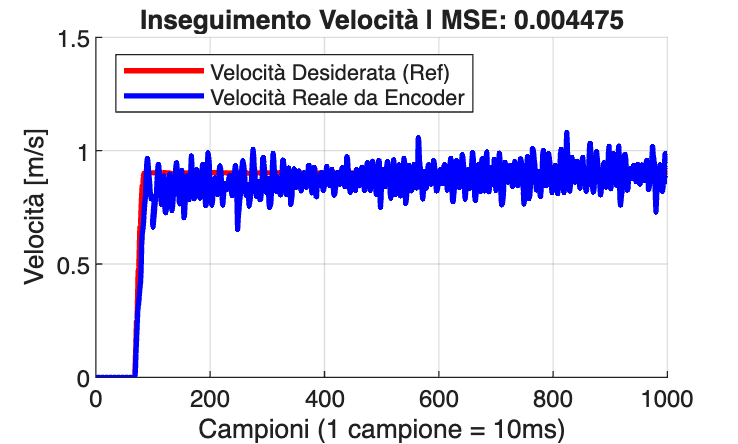


campioni = 1000; 
for i = 1:campioni
    try
        data_str = readline(s);
        data_split = split(data_str, ',');
        
        if length(data_split) == 3 && startsWith(data_split(1), "R")
            
            v_ref = str2double(data_split(2));
            v_real = str2double(data_split(3));
            
            % --- CALCOLO MINIMI QUADRATI (MSE) ---
            errore_attuale = v_ref - v_real;
            somma_errori_quadrati = somma_errori_quadrati + (errore_attuale^2);
            campioni_validi = campioni_validi + 1;
            
            mse_attuale = somma_errori_quadrati / campioni_validi;
            
            % Aggiorna il titolo del grafico con il valore in tempo reale
            title(sprintf('Inseguimento Velocità | MSE: %.6f', mse_attuale));
            
            % Disegna i punti
            addpoints(h_ref, campioni_validi, v_ref);
            addpoints(h_real, campioni_validi, v_real);
            
            drawnow limitrate; 
        end
    catch
        continue;
    end
end


disp('Acquisizione completata.');

Acquisizione completata.


fprintf('MSE Finale: %.6f\n', mse_attuale);

MSE Finale: 0.004475


clear s;